## Spike detection and spike rate analysis week 2, tutorial 2

In this live script we will read spike data into matlab with spike times aligned to auditory stimulus, recreate a raster plot aligned to stimulus and produce a Peristimulus time histogram (PSTH)

Tutorial using data from [https://github.com/yannikbauer/Raster_PSTH_SDF](https://github.com/yannikbauer/Raster_PSTH_SDF)

**OBS: 1) all sections with % $$$ should be completed with a line of code**

**          2) some lines that have to be completed are commented (%) and should be completed and uncommented for them to run (remove the % before the line in the script)**

**          3) after completing all fields and verifying the code produces the effects you want, save the file with the same W2T2_yourlastname . example: W2T2_costa.mlx**

**          4) in case of difficulties with creating variables, arrays, indexing, for etc... check the past tutorials solutions and the warm_up exercises**

clc
close all
clear

# Part 1 - Read the spike data 

1. load the electrical recordings

load('sptimes.mat')


2. verify what kind of variable is contained in the opened .mat file

class(sptimes)

**Inspect the data**

**A**. What is the data size?

Create a variable called datasize that contains the size of the loaded data in rows x columns

datasize = 

  % $$$


Each of the multiple cells in sptimes corresponds to a different trial and inside each cell in sptimes it contains all the timepoints when a spike was detected (in secs) in that trial.

**B**. Set the number of trials in this dataset?

TIP: use either the values in datasize or the function *length*

ntrials = 

 % $$$

**C**. What is the size of the last and second to last cell in sptimes?

Use indexing of the desired cell with { } . Since these are cells, their sizes can vary from one cell to the other. It is a way to store data of trials with different numbers of spikes

Use disp() to display the size of the first dimension (number of rows) of those cells 

TIP: You can confirm it is the right response by looking at each cell in the variable sptimes in the Workspace

 % $$$
 % $$$

**D**. Try to create a array with two columns:

one column has the values of the last cell; the second column has values of the second to last cell

TIP: use [ ] to concatenate two single column vectors. see *warm_up.mlx*

TIP2: **[a, b]** and **[a; b]** result in different matrices

array = 

 % $$$

**E**. Why can't the two rows be side by side? How can the data be aggregated into a single array?

(Concatenate in the correct way after testing this)

Write your answer below:

% Answer

% 

**F**. What is the size of each cell in sptimes?

TIP: initialize an empty variable and add the length of each cell there

scells = []; % vector where all sizes of each cell should be stored

for c = 1:length(sptimes)
     % scells(c) =  ;% $$$
end
disp(scells)

**G**. What is the mean of spikes per trial?

TIP: Use mean() or sum()/ntrials. Should reach the same result

avg_spikeptrial =

 % $$$

# Part 2 - Create a raster plot of the spikes 

**Warm up** - Plot the first line of a raster plot (spikes in trial y) at the position y = trial

trial = 10;
figure;
plot(sptimes{trial}, trial, 'g.', 'MarkerSize', 10)

3. open a figure and prepare a "subplot" with two panels stacked

figure('Units','normalized','Position',[0 0 .5 1])
ax = subplot(2,1,1); hold on

4. For each trial, plot dots at every x with a spike. Keep one line for each trial so that spikes are arranged in a raster plot with trials distributed over the y axis. 

If ntrials has not been defined before use ntrials = 35, otherwise use the same as above

TIP: use for loops across all trials

TIP2: for the position of each spike in time (x) you'll need a y value. Which value should be used to get all spikes plotted in a single y value (trial)?

TIP3: with plot you can set a single y value for several xs and get them all within a single line

5. Make if so that the plot is drawn starting from the top (last trial) to the bottom (first trial)

TIP: you'll need to change the way the for loop runs

% ntrials =  % $$$

for itrial = 1:ntrials

     % xspikes  =  ;   % Get all spikes of respective trial % $$$
     % yspikes  =   ;   % y values(trials) % $$$

    % plot(xspikes, yspikes, 'k.') % $$$
      
end
% set figure limits to last trial and to end of the recording window
ax.XLim             = [-.2 .3];
ax.YLim             = [0 ntrials];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Trials';

Example of the plot you should produce

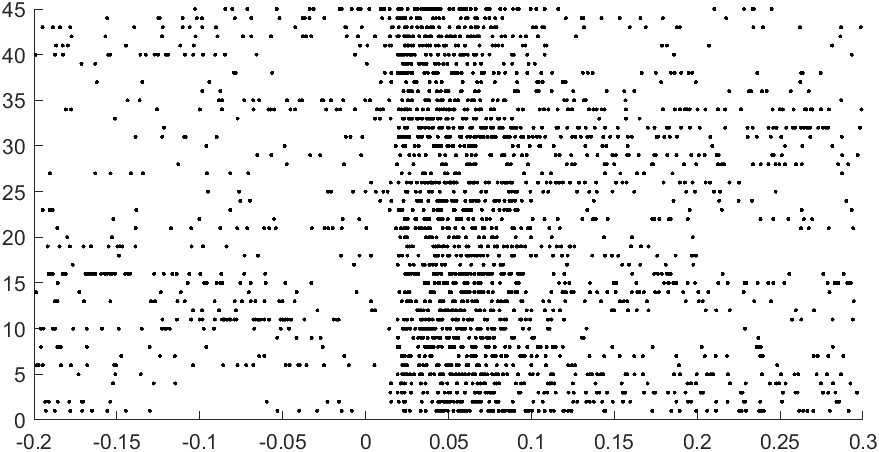

# Part 3 - Create a PSTH 

6 Add all spike times to a single vector

TIP: use a similar notation as before with [ ]. 

TIP2: check *warm_up.mlx* section Concatenate 2 for an introduction of how to carry out this task

%% Peristimulus time histogram (PSTH)

% intialize vector for all spikes
allspike = [];

% loop across all cells and get the values into a single column vector
for itrial = 1:length(sptimes)
     % Concatenate spikes of current trial to allspike
     % allspike = ;   % $$$
end

7. Based on the spike times what is the minimum time point before the stimulus and the maximum after

TIP: use the functions *min* and *max *

min_t = 

max_t = 

% min_t = % $$$
% max_t =  % $$$

8. Create a histogram with all spike timings and by segmenting data into nbins

A. set nbins to the desired number of bins (between 50 and 100 are ok)

B: set the length of each trial (see above min and max times; trials are not 1sec long. Can be approximated)

C. get the length of each trial in msecs

******histogram* makes the histogram and automatically plots it

% nbins               = ; % $$$ number of bins of choice
% trilength_secs      = ; % $$$ trial length in seconds
% trilength_msec      = ;% $$$ trial length in milliseconds


ax                  = subplot(2,1,2);
h                   = histogram(allspike,nbins);
h.FaceColor         = 'k';

% ___________ set up axis, color and scaling of the figure ___________ %
mVal                = max(h.Values)+round(max(h.Values)*.1);
ax.XLim             = [-.2 .3];
ax.YLim             = [0 mVal];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';

% Fix the y axis to represent spikes/sec
slength             = trilength_msec;                                  % Length of signal trace [ms]
bdur                = slength/nbins;                        % Bin duration in [ms]
nobins              = 1000/bdur;                            % No of bins/sec
for iLab = 1:length(ax.YTickLabel)
    lab             = str2num(ax.YTickLabel{iLab});
    conv            = (lab / length(sptimes)) * nobins; 	% Convert to [Hz]: avg spike count * bins/sec
    newlabel{iLab}  = num2str(round(conv));                 % Change YLabel
end
ax.YTickLabel       = newlabel;
ax.YLabel.String  	= 'Firing Rate [Hz]';

# Final Question 

9a. What is approximately the baseline firing rate when there's no stimulus?

% Answer:

%

9b. What is approximately the increase in the firing rate from baseline to stimulus? (answer Hz or in fold increase in firing rate)

% Answer:

%

# Review:

You should have values and answers for

Part 1 - A,  B, C, D, E, F, G

Part 2 - 4, 5 should produce the raster plot of the spikes

Part 3 - 6, 7, 8 should produce a histogram with firing rate x time

Final Question - 9a, 9b